# Hamamatsu Imaging with Two Cameras (Acquisition Only Rebuild)

说明： 1. 本文件只保留采集流程，不再继续拼接在线分析部分。 2. 脚本按“可单 section 调试”的方式组织，每段都尽量说明依赖和产物。 3. local functions 放在文件末尾，前面的 section 可以直接调用。

clear all;
clc;
sca;
imaqreset;

## Initialization

This rebuild keeps only the acquisition path. Method/record allocation is now stateful within the current run: 1. gather configuration and transient runtime state 2. freeze a new MethodsN_note folder once output is finalized 3. allocate RecN only when recording is about to start

单 section 运行提示： - 这是建议最先运行的 section。 - 这里创建本次运行共享的状态变量，但不会提前分配 method/record 编号。

root_path = 'E:\1_Data\YHY\260409_WT-POA_NAVI3-ST_sCy5';
if ~exist(root_path, "dir")
    % 先确保数据根目录存在，后面所有 MethodsN / RecN 都从这里往下创建。
    mkdir(root_path);
end

schema_version = "1.0.0";
recordmodes = {'record', 'visualstim'};
recordmode = recordmodes{1};

% Runtime IDs stay empty until the corresponding stage is reached.
device_list = {};
method_note = "default";
method_id = [];
method_path = "";
method_frozen = false;
record_id = [];
record_path = "";
record_time_str = "";

registration_figure_handle = [];
daq_preview_figure_handle = [];

hardwareInfo = struct();
cameraSpec = struct();
stimSpec = struct();
stimRuntime = struct();
registrationInfo = defaultRegistrationInfo();
hikronInfo = defaultHikronInfo();
methodManifest = struct();
recordManifest = struct();
cycleManifest = struct();

cfg = struct();
cfg.schema_version = schema_version;
cfg.methindex = [];
cfg.recindex = [];

## Connect to Camera

依赖： - Initialization 已运行。

产物： - info / num.cameras / device_list - v / src - hardwareInfo.cameras

imageAcquisitionExplorer;

ans =   ToolboxPreferencesManager - 属性:

    GetPrefListener: [1×1 handle.listener]
    SetPrefListener: [1×1 handle.listener]



% 读取 Hamamatsu 适配器下当前可见的相机。
info = imaqhwinfo('hamamatsu');
num.cameras = length(info.DeviceInfo);
fprintf('%0d camera(s) found.\n', num.cameras);

1 camera(s) found.



for i = 1:num.cameras
    % 设备名后面会参与 DAQ 端口匹配，所以这里先保存下来。
    dev_name = info.DeviceInfo(i).DeviceName;
    device_list{end+1} = dev_name; %#ok<SAGROW>
    fprintf('Device ID %d: %s\n', i, dev_name);
end

Device ID 1: C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8



v = cell(num.cameras, 1);
src = cell(num.cameras, 1);
for i = 1:num.cameras
    % 先按默认全画幅格式建对象；后面的相机配置 section 会按 bin 重建。
    v{i} = videoinput("hamamatsu", i, "MONO16_2304x2304_Fast");
    src{i} = getselectedsource(v{i});
end
fprintf('Camera(s) linked.\n');

Camera(s) linked.



hardwareInfo.cameras.detected = num.cameras;
hardwareInfo.cameras.deviceList = device_list;
hardwareInfo.cameras.info = info.DeviceInfo;

## Connect to DAQ

Keep a parallel label list for DAQ channels. Later logic builds outputs by these semantic tags instead of raw channel IDs.

依赖： - Connect to Camera 已运行，因为这里要根据相机设备名决定端口映射。

产物： - d.out / d.in - d.channeltypes - hardwareInfo.daq

daqreset;
trigger = true;
camera_ports = {'port0/line9', 'port0/line10'};
input_ports = {'ctr1', 'ctr2'};
camera_names = { ...
    'C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8'; ...
    'C14440-20UP, S/N: 002325, Bus: USB3'};

d = struct();
d.out = daq('ni');
d.in = daq('ni');
d.in.Rate = 2000;
d.device = 'Dev1';
d.channeltypes = struct('out', {{}}, 'in', {{}}, 'daq', {{}});

dinfo = daqlist("ni");
hardwareInfo.daq.list = dinfo;
hardwareInfo.daq.device = d.device;
hardwareInfo.daq.inputRate = d.in.Rate;

if ~isempty(d.out.Channels)
    % 支持重复运行本段：先清旧通道，再按当前连接状态重建。
    removechannel(d.out);
end
if ~isempty(d.in.Channels)
    removechannel(d.in);
end

addinput(d.in, d.device, "ai0", "Voltage");
% 这个模拟输入主要用于启动 DAQ 输入对象并提供统一时间轴。
d.channeltypes.in{end+1} = 'Clock';

for i = 1:num.cameras
    indexC = strfind(camera_names, info.DeviceInfo(i).DeviceName); %#ok<STRCL1>
    index = find(~cellfun('isempty', indexC), 1, 'first');
    if isempty(index)
        error('Camera %d (%s) was not found in camera_names.', i, info.DeviceInfo(i).DeviceName);
    end

    % 数字输出用于给相机发外触发脉冲。
    addoutput(d.out, d.device, camera_ports{index}, 'Digital');
    d.channeltypes.out{end+1} = ['camera_DO_' device_list{i}];

    % 计数输入用于采集相机回传的 timing / frame 事件。
    addinput(d.in, d.device, input_ports{index}, 'EdgeCount');
    d.channeltypes.in{end+1} = ['camera_timing_' device_list{i}];
end

addinput(d.in, d.device, 'ctr0', "Position");
% Internalstamp 通道用于把视觉刺激翻页事件打到 DAQ 时间线上。
d.channeltypes.in{end+1} = 'Internalstamp';
addoutput(d.out, d.device, 'port0/line7', 'Digital');
d.channeltypes.out{end+1} = 'Internalstamp';

resetcounters(d.in);
% 把所有输出先拉低，避免脚本重跑后外设停留在高电平状态。
write(d.out, zeros(1, numel(d.out.Channels)));

fprintf('\n--- NI-DAQ Summary ---\n');


--- NI-DAQ Summary ---


fprintf('Input rate: %.1f Hz\n', d.in.Rate);

Input rate: 2000.0 Hz


for j = 1:numel(d.in.Channels)
    fprintf('IN  %d: %-15s -> %s\n', j, d.in.Channels(j).ID, d.channeltypes.in{j});
end

IN  1: ai0             -> Clock
IN  2: ctr1            -> camera_timing_C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8
IN  3: ctr0            -> Internalstamp


for j = 1:numel(d.out.Channels)
    fprintf('OUT %d: %-15s -> %s\n', j, d.out.Channels(j).ID, d.channeltypes.out{j});
end

OUT 1: port0/line9     -> camera_DO_C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8
OUT 2: port0/line7     -> Internalstamp


fprintf('----------------------\n');

----------------------


## Set light source

The last N selected light sources are reserved for imaging, where N is the number of active cameras.

依赖： - Connect to DAQ 已运行。

产物： - lightls.used / lightls.img / lightls.stim - hardwareInfo.light

单 section 运行提示： - 本段支持重复运行。 - 重跑时会先裁掉旧的附加光源通道，再按当前 light_channel 重新追加。

channel_group = {'Laser405', 'Laser445', 'LEDcyan', 'LEDgreen', 'LEDred'};
light_port = {"port0/line23", "port0/line11", "port0/line12", "port0/line16", "port0/line18"};
colors = {'m', 'b', 'b', 'g', 'r'};
light_channel = [5];

if length(light_channel) - num.cameras > 1
    error('Too many stimulation light sources were requested for the current acquisition logic.');
elseif length(light_channel) < num.cameras
    warning('The number of light sources is smaller than the number of cameras.');
end

lightls = struct();
% used 保存本次实验要参与的全部光源。
lightls.used = channel_group(light_channel);
% 最后 num.cameras 个光源固定作为成像光。
lightls.img = lightls.used(end - num.cameras + 1:end);
% 其他光源视为刺激光，并保持用户的原始顺序。
lightls.stim = setdiff(lightls.used, lightls.img, 'stable');
num.imlsrc = length(lightls.img);
num.stlsrc = length(lightls.stim);

if length(d.out.Channels) > num.cameras + 1
    % d.out 的前 num.cameras+1 个通道属于基础通道：
    % 相机触发 + Internalstamp。其后才是本段追加的光源通道。
    d.channeltypes.out = d.channeltypes.out(1:(num.cameras + 1));
    removechannel(d.out, (num.cameras + 2):length(d.out.Channels));
end

for i = 1:length(light_channel)
    % 为每个入选光源追加数字输出。
    addoutput(d.out, d.device, light_port{light_channel(i)}, 'Digital');
    if i <= num.stlsrc
        d.channeltypes.out{end+1} = ['light_stim_DO_' lightls.used{i}];
    else
        d.channeltypes.out{end+1} = ['light_img_DO_' lightls.used{i}];
    end

    if light_channel(i) == 2
        % Laser445 额外支持 AO 电压步进，因此这里再追加一个模拟输出。
        addoutput(d.out, d.device, "ao2", "Voltage");
        d.channeltypes.out{end+1} = ['light_stim_AO_' lightls.used{i}];
    end
end

hardwareInfo.light = struct( ...
    'channelGroup', {channel_group}, ...
    'lightPort', {light_port}, ...
    'colors', {colors}, ...
    'selectedChannels', light_channel, ...
    'used', {lightls.used}, ...
    'imaging', {lightls.img}, ...
    'stimulation', {lightls.stim});

## Align Two Cameras

baseROI is the only ROI source of truth. Any registration offset is applied on top of baseROI so rerunning sections does not accumulate drift.

依赖： - Connect to Camera 已运行。

产物： - baseROI - registrationInfo - registration_figure_handle - cameraSpec.baseROI / cameraSpec.registeredROI

单 section 运行提示： - 这里只负责计算和缓存 registrationInfo。 - 不再像旧版那样把 0_register_image.* 直接写到 root_path。

baseROI = cell(num.cameras, 1);
for i = 1:num.cameras
    baseROI{i} = [896 896 512 512];
end
cameraSpec.baseROI = baseROI;
cameraSpec.registrationApplied = false;

for i = 1:num.cameras
    % 配准前先把相机 ROI 放回共同基准，以免沿用上一次调试残留状态。
    v{i}.ROIPosition = baseROI{i};
end

if num.cameras >= 2
    im25 = getsnapshot(v{1});
    im26 = getsnapshot(v{2});
    im25 = im25';
    % im26 = im26;

    tic;
    registermode = 'multimodal';
    [optimizer, metric] = imregconfig(registermode);
    tform = imregtform(im25, im26, 'translation', optimizer, metric);
    fprintf('Registered after %0d s.\n', round(toc));

    x_offset = tform.T(3, 1);
    y_offset = tform.T(3, 2);
    fprintf('Offset x = %.2f, y = %.2f\n', x_offset, y_offset);

    registered_im25 = imtranslate(im25, [x_offset, y_offset]);
    registration_figure_handle = figure('Name', 'Camera Registration', 'Color', 'w');
    subplot(1, 3, 1);
    imshowpair(im25, im26);
    title('Before Registration');
    subplot(1, 3, 2);
    imshowpair(registered_im25, im26);
    title('After Registration');

    registrationInfo = struct();
    % registrationInfo 保存“规则 + 实际结果”，供后续反复重算 ROI。
    registrationInfo.mode = registermode;
    registrationInfo.offsetXY = [x_offset, y_offset];
    registrationInfo.referenceCamera = 2;
    registrationInfo.movingCamera = 1;
    registrationInfo.baseROI = baseROI;
    registrationInfo.tform = tform;
    registrationInfo.optimizer = optimizer;
    registrationInfo.metric = metric;
    registrationInfo.applied = true;
    registrationInfo.status = "computed";
    registrationInfo.notes = "ROI is always recomputed from baseROI plus registration offset.";

    % 按当前 registrationInfo 一次性重算全部相机 ROI。
    appliedROI = recomputeROIFromBase(baseROI, registrationInfo, ones(1, num.cameras));
    for i = 1:num.cameras
        % 每次应用偏移都重新从 baseROI 出发，避免多次运行 section 后 ROI 漂移。
        % 把重算后的 ROI 写回当前相机对象。
        v{i}.ROIPosition = appliedROI{i};
    end
    cameraSpec.registrationApplied = true;
    cameraSpec.registeredROI = appliedROI;

    im25 = getsnapshot(v{1});
    im26 = getsnapshot(v{2});
    im25 = im25';
    subplot(1, 3, 3);
    imshowpair( im25,im26);
    title('Re-Acquired Preview');
end

    baseROI = cell(num.cameras, 1);
for i = 1:num.cameras
    baseROI{i} = [896 896 512 512];
end
cameraSpec.baseROI = baseROI;
cameraSpec.registrationApplied = false;
appliedROI = recomputeROIFromBase(baseROI, registrationInfo, ones(1, num.cameras));
    for i = 1:num.cameras
        % 每次应用偏移都重新从 baseROI 出发，避免多次运行 section 后 ROI 漂移。
        % 把重算后的 ROI 写回当前相机对象。
        v{i}.ROIPosition = appliedROI{i};
    end
    cameraSpec.registrationApplied = true;
    cameraSpec.registeredROI = appliedROI;


## Configure Default Device Properties for Voltage Recording

Rebuild camera objects when binning changes, then reapply ROI from baseROI + registrationInfo instead of reusing mutated ROI state.

依赖： - Connect to Camera 已运行。 - 若希望拿到注册后的 ROI，本段应在 Align Two Cameras 之后执行。

产物： - 相机最终采集参数 - cameraSpec.cameras

单 section 运行提示： - 这是可以反复调试的 section。 - 反复运行不会让 ROI 越跑越偏，因为每次都重新计算。

triggermode = 'immediate';
% bin 保存每台相机当前的 binning 设置。
bin = ones(1, num.cameras);
% eptime 是采集曝光时间，后续会同时影响相机和刺激同步估计。
eptime = 2.4931e-03;
cameraSpec.bin = bin;
cameraSpec.exposureTime = eptime;

for i = 1:num.cameras
    % 逐台相机处理，保证每台相机都能独立设置 bin / ROI / trigger。
    b = bin(i);
    if b == 1
        binmode = 'MONO16_2304x2304_Fast';
    elseif b == 2
        binmode = "MONO16_BIN2x2_1152x1152_Fast";
    elseif b == 4
        binmode = "MONO16_BIN4x4_576x576_Fast";
    else
        error('Unsupported bin value %d for camera %d.', b, i);
    end

    % 默认认为需要重建，只有当当前对象格式已经匹配时才跳过。
    need_reinit = true;
    if exist('v', 'var') && length(v) >= i && isvalid(v{i}) && strcmp(v{i}.VideoFormat, binmode)
        need_reinit = false;
    end

    if need_reinit
        % 只有在目标视频格式变化时才重建对象，避免不必要地丢失句柄状态。
        v{i} = videoinput("hamamatsu", i, binmode);
        src{i} = getselectedsource(v{i});
        fprintf('Camera %d switched to bin %d.\n', i, b);
    end

    % ROI 的最终值由 baseROI、registrationInfo 和 bin 共同决定。
    % 当前 ROI 始终从规则重算，不读取历史变更后的 ROIPosition。
    currentROI = recomputeSingleROI(baseROI{i}, registrationInfo, i, b);
    v{i}.ROIPosition = currentROI;

    % TriggerRepeat=0 表示一次启动后只执行当前这次采集任务。
    v{i}.TriggerRepeat = 0;
    v{i}.FramesPerTrigger = Inf;
    src{i} = getselectedsource(v{i});
    % 把本 section 设定的曝光时间写回相机 source。
    src{i}.ExposureTime = eptime;
    triggerconfig(v{i}, triggermode);

    if trigger
        % 统一配置成外触发启动，并把 vsync 作为硬件同步输出。
        src{i}.TriggerSource = 'external';
        src{i}.TriggerPolarity = "positive";
        src{i}.TriggerMode = 'start';
        src{i}.OutputTriggerKindOpt1 = 'programable';
        src{i}.OutputTriggerSourceOpt1 = 'vsync';
        src{i}.OutputTriggerPolarityOpt1 = 'positive';
    end

    % 将每台相机最终实际生效的配置写进 cameraSpec，供 manifest 记录。
    cameraSpec.cameras(i) = struct( ... %#ok<SAGROW>
        'index', i, ...
        'deviceName', device_list{i}, ...
        'bin', b, ...
        'videoFormat', string(v{i}.VideoFormat), ...
        'ROIPosition', currentROI, ...
        'exposureTime', eptime, ...
        'triggerMode', string(triggermode));
end

fprintf(['\n' repmat('=', 1, 40) '\n']);

fprintf('Camera Configuration Summary\n');

Camera Configuration Summary


for i = 1:num.cameras
    actualROI = v{i}.ROIPosition;
    fprintf('Cam %d: Bin=%d | Format=%s\n', i, bin(i), v{i}.VideoFormat);
    fprintf('       ROI: [X:%d Y:%d W:%d H:%d] | Exp: %.2fms\n', actualROI(1), actualROI(2), actualROI(3), actualROI(4), eptime * 1000);
end

Cam 1: Bin=1 | Format=MONO16_2304x2304_Fast


       ROI: [X:896 Y:896 W:512 H:512] | Exp: 2.49ms


fprintf([repmat('=', 1, 40) '\n']);

## Screen stimulation preparation

stimSpec is the experiment specification. stimRuntime stores live PTB handles/runtime fields and must not redefine the global record mode as the old script did.

依赖： - 相机配置 section 建议已运行，因为 stimSpec.camFPS 依赖 eptime。

产物： - stimSpec：应该进入 manifest 的实验规格 - stimRuntime：窗口和纹理等运行时句柄

单 section 运行提示： - 本段会打开 PTB 窗口。 - 如果只是想改刺激参数，重跑本段即可，但要注意窗口资源的关闭状态。

stimSpec = struct();
% enabled 控制是否初始化 PTB 刺激运行环境。
stimSpec.enabled = true;
stimSpec.mode = recordmodes{2};
% 这里先给默认值，真正开窗后会按 windowRect 回写实际分辨率。
stimSpec.videoWidth = 1024;
stimSpec.videoHeight = 768;
stimSpec.duration = 1;
stimSpec.isi = 2;
stimSpec.numorien = 8;
% orientations 给出完整一轮 drifting grating 的方向集合。
stimSpec.orientations = 0:360 / stimSpec.numorien:360 * (1 - 1 / stimSpec.numorien);
stimSpec.amp = 0.5;
stimSpec.SF = 0.04;
stimSpec.TF = 2;
stimSpec.distToScreen = 9;
stimSpec.screenWidthCm = 11;
stimSpec.totalVisualAngle = 2 * atand((stimSpec.screenWidthCm / 2) / stimSpec.distToScreen);
% pixelsPerDegree 和 cpp 会在真正拿到窗口分辨率后重算。
stimSpec.pixelsPerDegree = [];
stimSpec.cps = stimSpec.TF;
stimSpec.cpp = [];
stimSpec.camFPS = 1 / eptime;
stimSpec.grayValue = 128;

% stimRuntime 只保存运行期句柄，不应被当成固定实验设计参数。
stimRuntime = struct('initialized', false, 'window', [], 'windowRect', [], 'gratingtex', [], 'grayTex', [], 'ifi', [], 'phaseinc', [], 'priority', []);
if stimSpec.enabled
    % 这里是真正的运行时初始化：开窗口、建纹理、读取 ifi。
    ListenChar(2);
    PsychDefaultSetup(2);
    screenNumber = max(Screen('Screens'));
    AssertOpenGL;
    Screen('Preference', 'WindowShieldingLevel', 0);
    Screen('Preference', 'SkipSyncTests', 0);
    Screen('Preference', 'Verbosity', 4);
    Screen('Preference', 'VisualDebugLevel', 3);

    [stimRuntime.window, stimRuntime.windowRect] = PsychImaging('OpenWindow', screenNumber, 0.5);
    stimRuntime.priority = MaxPriority(stimRuntime.window);
    Priority(stimRuntime.priority);

    % 最新 PTB 设置里，实际刺激分辨率以当前窗口大小为准。
    stimSpec.videoWidth = stimRuntime.windowRect(3);
    stimSpec.videoHeight = stimRuntime.windowRect(4);
    stimSpec.pixelsPerDegree = stimSpec.videoWidth / stimSpec.totalVisualAngle;
    stimSpec.cpp = stimSpec.SF / stimSpec.pixelsPerDegree;

    stimRuntime.gratingsize = ceil(sqrt(stimSpec.videoWidth^2 + stimSpec.videoHeight^2));
    stimRuntime.gratingtex = CreateProceduralSineGrating(stimRuntime.window, stimRuntime.gratingsize, stimRuntime.gratingsize, [0.5 0.5 0.5 0.0]);
    stimRuntime.grayArray = uint8(ones(10, 10) * stimSpec.grayValue);
    stimRuntime.grayTex = Screen('MakeTexture', stimRuntime.window, stimRuntime.grayArray);
    stimRuntime.ifi = Screen('GetFlipInterval', stimRuntime.window);
    stimRuntime.phaseinc = (stimSpec.cps * 360) * stimRuntime.ifi;
    stimRuntime.initialized = true;
end



PsychJavaTrouble: Will now try to add the PsychJava folder to Matlabs dynamic classpath...
PsychJavaTrouble: Added PsychJava folder to dynamic class path. Psychtoolbox Java commands should work now!
INFO: Problem may be fixed for this session. Let's see...
INFO: Yep! Still, please fix the problem properly asap.




PTB-INFO: This is Psychtoolbox-3 for Microsoft Windows, under Matlab 64-Bit (Version 3.0.19 - Build date: Jul 31 2024).
PTB-INFO: OS support status: Windows 11 (Version 11.0) is not supported.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid support, support memberships and other commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.

PTB-INFO: Proper timing and timestamping of visual stimulus onset is not reliably supported at all
PTB-INFO: when running in windowed mode (non-fullscreen). If PTB aborts with 'Synchronization failure'
PTB-INFO: you can disable the sync test via call to Screen('Preference', 'SkipSyncTests', 2); .
PTB-INFO: You won't get proper stimulus onset ti

Compiling all shaders matching BasicSineGratingShader * into a GLSL program.
Building a fragment shader:Reading shader from file E:\0_Code\Psychtoolbox-3-3.0.19.15\Psychtoolbox\PsychOpenGL\PsychGLSLShaders\BasicSineGratingShader.frag.txt ...
Building a vertex shader:Reading shader from file E:\0_Code\Psychtoolbox-3-3.0.19.15\Psychtoolbox\PsychOpenGL\PsychGLSLShaders\BasicSineGratingShader.vert.txt ...



recordmode = recordmodes{2};

## PTB 单次播放 loop 测试 section

本段功能： - 用于单独测试 PTB 刺激播放逻辑，一次只播放一个方向。 - 每次运行本段，stim_count 会往后推进一个方向，方便你单 section 逐个检查。 - 这是调试 section，不分配 MethodsN，不创建 RecN，也不写正式采集记录。

依赖： - stimulation section 已经运行，并且成功初始化了 stimRuntime.window / stimRuntime.ifi / stimRuntime.gratingtex。 - 如果你当前窗口已经打开到一半，本段会直接复用当前窗口和工作区变量。

单 section 运行提示： - 本段不会 clear 工作区变量。 - 本段不会 sca 关闭已经打开的 PTB 窗口。 - 如果 stim_count 不存在，会自动从第 1 个方向开始。

if ~stimSpec.enabled || ~isfield(stimRuntime, 'initialized') || ~stimRuntime.initialized || isempty(stimRuntime.window)
    error('PTB playback test requires the stimulation section to be initialized first.');
end

if ~exist('stim_count', 'var')
    stim_count = 1;
end

if stim_count > length(stimSpec.orientations)
    stim_count = 1;
    fprintf('>>> 已完成一轮 PTB 测试播放，现在重置回第 1 个方向。\n');
end

current_angle = stimSpec.orientations(stim_count);

try
    % 先抓取新的翻页时间基准，后续 ISI 和刺激都以这个时间为参考。
    vbl = Screen('Flip', stimRuntime.window);

    % 先播放 ISI 灰屏，便于观察节奏是否正常。
    numFramesISI = round(stimSpec.isi / stimRuntime.ifi);
    for f = 1:numFramesISI
        Screen('FillRect', stimRuntime.window, 0.5);
        vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi);
    end

    % 把 grating 放在当前窗口中央。
    phase = 0;
    numFramesStim = round(stimSpec.duration / stimRuntime.ifi);
    dstRect = CenterRectOnPoint([0 0 stimRuntime.gratingsize stimRuntime.gratingsize], ...
        stimSpec.videoWidth / 2, stimSpec.videoHeight / 2);

    % 逐帧播放 drifting grating。
    for f = 1:numFramesStim
        phase = phase + stimRuntime.phaseinc;
        Screen('DrawTexture', stimRuntime.window, stimRuntime.gratingtex, [], dstRect, ...
            current_angle, [], [], [], [], [], [phase, stimSpec.cpp, stimSpec.amp, 0]);
        vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi);

        if f == 1
            fprintf('>>> PTB 测试播放: 方向 %d/%d | 角度 %.1f 度\n', ...
                stim_count, length(stimSpec.orientations), current_angle);
            % 如需在第一帧打 DAQ 脉冲，可在这里插入 write(d.out, ... )。
        end
    end

    % 播放结束后回到灰屏，但不关闭窗口，方便继续单 section 调试。
    Screen('FillRect', stimRuntime.window, 0.5);
    vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi); %#ok<NASGU>

    % 记录下一个待播放方向，便于再次运行本 section 时继续往后测。
    stim_count = stim_count + 1;
catch ME
    % 保留现场工作区状态，直接把错误抛出，方便你排查。
    rethrow(ME);
end



PTB-ERROR: Screen('Flip'); beamposition timestamping computed an *impossible stimulus onset value* of 189804.153465 secs, which would indicate that
PTB-ERROR: stimulus onset happened *before* it was actually requested! (Earliest theoretically possible 189804.168316 secs).

PTB-ERROR: Some more diagnostic values (only for experts): rawTimestamp = 189804.169916, scanline = 536
PTB-ERROR: Some more diagnostic values (only for experts): line_pre_swaprequest = 480, line_post_swaprequest = 529, time_post_swaprequest = 189804.169730
PTB-ERROR: Some more diagnostic values (only for experts): preflip_vblcount = 0, preflip_vbltimestamp = 189804.153600
PTB-ERROR: Some more diagnostic values (only for experts): postflip_vblcount = 0, postflip_vbltimestamp = -1.000000, vbltimestampquery_retrycount = 0

PTB-ERROR: This error can be due to either of the following causes:
PTB-ERROR: Very unlikely: Something is broken in your systems beamposition timestamping. I've disabled high precision
PTB-ERROR: 

>>> PTB 测试播放: 方向 1/8 | 角度 0.0 度


## PTB 全长播放测试 section

本段功能： - 按照 stimSpec.orientations 的完整顺序，把一整轮 drifting grating 全部播放完。 - 用于你在单 section 模式下检查整轮播放节奏、方向切换、窗口状态和主观显示效果。 - 本段只做 PTB 画面播放，不启动相机，不启动 DAQ，不写正式采集数据。

依赖： - stimulation section 已经运行，并且 stimRuntime 已成功初始化。 - 当前 PTB 窗口仍然有效，或者你已经重新运行过 stimulation section。

单 section 运行提示： - 本段不会 clear 工作区变量。 - 本段不会 sca 关闭现有窗口。 - 本段每次都会从第 1 个方向开始完整播放一轮。

if ~stimSpec.enabled || ~isfield(stimRuntime, 'initialized') || ~stimRuntime.initialized || isempty(stimRuntime.window)
    error('PTB full-length playback test requires the stimulation section to be initialized first.');
end

try
    % 用新的翻页时间作为全轮播放的起点，保证后续 ISI 和刺激都挂在当前时间轴上。
    vbl = Screen('Flip', stimRuntime.window);

    % 逐个方向完整播放一轮，与正式 visualstim 的方向顺序保持一致。
    for angle = stimSpec.orientations
        % 每个方向开始前先播放一段灰屏 ISI，便于观察方向切换节奏。
        numFramesISI = round(stimSpec.isi / stimRuntime.ifi);
        for f = 1:numFramesISI %#ok<NASGU>
            Screen('FillRect', stimRuntime.window, 0.5);
            vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi);
        end

        % 当前方向的 grating 仍然画在窗口中央。
        phase = 0;
        numFramesStim = round(stimSpec.duration / stimRuntime.ifi);
        dstRect = CenterRectOnPoint([0 0 stimRuntime.gratingsize stimRuntime.gratingsize], ...
            stimSpec.videoWidth / 2, stimSpec.videoHeight / 2);

        fprintf('>>> PTB 全长测试播放 | 当前角度 %.1f 度\n', angle);

        % 逐帧推进当前方向的 drifting grating。
        for f = 1:numFramesStim %#ok<NASGU>
            phase = phase + stimRuntime.phaseinc;
            Screen('DrawTexture', stimRuntime.window, stimRuntime.gratingtex, [], dstRect, ...
                angle, [], [], [], [], [], [phase, stimSpec.cpp, stimSpec.amp, 0]);
            vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi);
        end
    end

    % 全轮播放结束后回到灰屏，但不关闭窗口，方便你继续调试别的 section。
    Screen('FillRect', stimRuntime.window, 0.5);
    Screen('Flip', stimRuntime.window);
catch ME
    % 出错时保留现场，不主动清理工作区或窗口。
    rethrow(ME);
end



PTB-ERROR: Screen('Flip'); beamposition timestamping computed an *impossible stimulus onset value* of 172179.816930 secs, which would indicate that
PTB-ERROR: stimulus onset happened *before* it was actually requested! (Earliest theoretically possible 172179.830972 secs).

PTB-ERROR: Some more diagnostic values (only for experts): rawTimestamp = 172179.832437, scanline = 506
PTB-ERROR: Some more diagnostic values (only for experts): line_pre_swaprequest = 454, line_post_swaprequest = 501, time_post_swaprequest = 172179.832310
PTB-ERROR: Some more diagnostic values (only for experts): preflip_vblcount = 0, preflip_vbltimestamp = 172179.817044
PTB-ERROR: Some more diagnostic values (only for experts): postflip_vblcount = 0, postflip_vbltimestamp = -1.000000, vbltimestampquery_retrycount = 0

PTB-ERROR: This error can be due to either of the following causes:
PTB-ERROR: Very unlikely: Something is broken in your systems beamposition timestamping. I've disabled high precision
PTB-ERROR: 

>>> PTB 全长测试播放 | 当前角度 0.0 度
>>> PTB 全长测试播放 | 当前角度 45.0 度
>>> PTB 全长测试播放 | 当前角度 90.0 度
>>> PTB 全长测试播放 | 当前角度 135.0 度
>>> PTB 全长测试播放 | 当前角度 180.0 度
>>> PTB 全长测试播放 | 当前角度 225.0 度
>>> PTB 全长测试播放 | 当前角度 270.0 度
>>> PTB 全长测试播放 | 当前角度 315.0 度


## Hikron section

依赖： - 当前版本只保留 Hikron 的状态占位，不做真实初始化。

单 section 运行提示： - 以后如果恢复 Hikron，请保持“只有初始化成功才 enabled=true”这条规则。

hikronRequested = false;
vh = [];
if hikronRequested
    hikronInfo.requested = true;
    hikronInfo.enabled = false;
    hikronInfo.status = "placeholder";
    hikronInfo.notes = "Requested but initialization logic is not rebuilt in this acquisition-only pass.";
end

## Output allocation: freeze a new method

This is the only place where a new method ID is allocated. Even if parameters later return to a previous configuration, we still freeze a fresh MethodsN_note folder and never reuse an older method.

依赖： - DAQ / light / camera / registration / stimulation 相关 section 已按需求运行。

产物： - method_id / method_path / method_frozen - methodManifest - registration.mat/png/fig - daq_output.mat/png - daq.mat

单 section 运行提示： - 每运行一次都会新建一个新的 MethodsN_note。 - 即使参数改回旧配置，也不会复用以前的 method。 cfg.t 统一保存本次方法对应的时间参数。

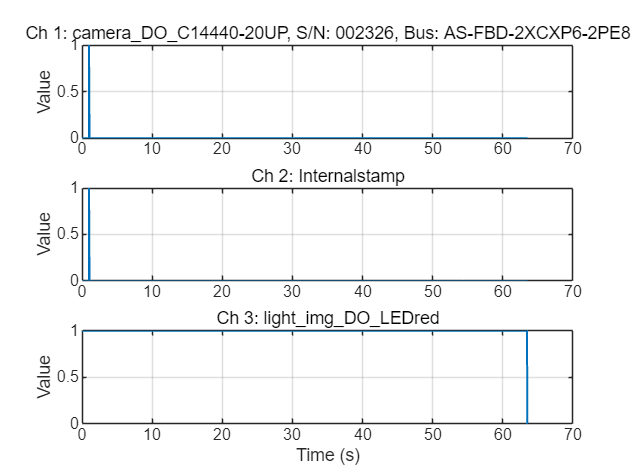

% recordmode = recordmodes{1};
%=============================
cfg.t = struct();
cfg.t.record = 60;
cfg.t.headlength = 1;
cfg.t.taillength = ceil(cfg.t.record/20)/2 + 1;
cfg.t.stim = 0.2;
cfg.t.stimdelay = 0.1;
cfg.t.stimcycle = 3;
% aostep 定义刺激 AO 的相对步进，后面会转换成实际电压。
d.aostep = [2, 5, 25];
d.aostep = 5 .* d.aostep ./ 100;

% label 用于生成 CamN_label 文件夹名和最终数据文件前缀。
cfg.label = {'Red15%_60s'};
cfg.cycles = 1;
cfg.t.rest = 60;
cfg.savetype = "tif";
%=============================
cfg.recordmode = recordmode; %recordmode = recordmodes{1}
cfg.hikron = hikronInfo.enabled;
cfg.schema_version = schema_version;
cfg.hardwareInfo = hardwareInfo;
cfg.cameraSpec = cameraSpec;
cfg.stimSpec = stimSpec;
cfg.stimRuntime = rmfield_if_exists(stimRuntime, {'window', 'windowRect', 'gratingtex', 'grayTex'});
cfg.registrationInfo = registrationInfo;
cfg.hikronInfo = hikronInfo;
cfg.lightls = lightls;

if length(cfg.label) ~= num.cameras
    error('Label count (%d) does not match the number of cameras (%d).', length(cfg.label), num.cameras);
end

% method_note 会直接写进目录名 MethodsN_note，可按当天实验手写备注修改。
method_note = "default";
[method_id, method_path] = allocate_method_id(root_path, method_note);
cfg.methindex = method_id;
method_frozen = true;

% Save all method-level artifacts only after the method is frozen.
% RecN and later cycles may reference this method, but must not mutate it.
% output_idx 表示本次 method 需要参与输出方案生成的通道索引。
output_idx = 1:numel(d.channeltypes.out);
% internal_idx 用于在 visualstim 模式下定位 stamp 通道。
internal_idx = find(contains(d.channeltypes.out, 'Internalstamp'), 1, 'first');
[cfg, output, signal] = buildOutputSignals(cfg, d, lightls, output_idx, internal_idx, recordmodes, stimSpec);

if ~exist(method_path, 'dir')
    mkdir(method_path);
end

% method 冻结后再统一保存注册结果，避免把临时文件散落在 root_path。
save(fullfile(method_path, 'registration.mat'), 'registrationInfo');
if ~isempty(registration_figure_handle) && isvalid(registration_figure_handle)
    saveas(registration_figure_handle, fullfile(method_path, 'registration.fig'), 'fig');
    saveas(registration_figure_handle, fullfile(method_path, 'registration.png'), 'png');
end

% 这里保存 method 级 DAQ 方案预览，便于人工核对输出通道设计是否正确。
daq_preview_figure_handle = visualizeOutputPreview(output, d.out.Rate, d.channeltypes.out(output_idx), cfg);
saveas(daq_preview_figure_handle, fullfile(method_path, 'daq_output.png'));

save(fullfile(method_path, 'daq_output.mat'), 'output');
save(fullfile(method_path, 'daq.mat'), 'd');

methodManifest = buildMethodManifest(schema_version, method_id, method_path, method_note, cfg, hardwareInfo, cameraSpec, stimSpec, stimRuntime, registrationInfo, hikronInfo, output);
saveManifestPair(fullfile(method_path, 'method_manifest'), methodManifest);

## Recording start

Record allocation happens after method freeze and creates a fixed folder tree: MethodsN_note/RecN_timestamp/Cycle1/Cam1_label

依赖： - Output allocation 已运行，且 method_frozen=true。

产物： - record_id / record_path - files_paths - recordManifest

单 section 运行提示： - 每运行一次都会在既定 MethodsN_note 下新增一个 RecN_timestamp。 - RecN 只是挂接到 method，不允许反向修改 method 内容。

if ~method_frozen || isempty(method_id) || strlength(method_path) == 0
    error('Method must be frozen before recording starts.');
end

record_time_str = char(strrep(string(datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss')), ':', '-'));
[record_id, record_path] = allocate_record_id(method_path, record_time_str);
cfg.recindex = record_id;

% 按固定规则创建 RecN/CycleN/CamN_label 目录树。
files_paths = createRecordPaths(record_path, cfg, num.cameras);
recordManifest = buildRecordManifest(schema_version, method_id, method_path, record_id, record_path, record_time_str, cfg, files_paths);
saveManifestPair(fullfile(record_path, 'record_manifest'), recordManifest);

fprintf('>>> Experiment start: %d cycle(s).\n', cfg.cycles);

>>> Experiment start: 1 cycle(s).


## Main execution engine

Each cycle writes its own manifest and sync/log artifacts. Temporary runtime variables are no longer treated as formal method records.

依赖： - Recording start 已运行。 - record 模式依赖 cfg.output。 - visualstim 模式依赖 stimRuntime 已有效初始化。

单 section 运行提示： - 正式采集建议从这个 section 顶部开始运行。 - 不建议跳过前面的准备 section，直接运行循环内部语句。

total_tic = tic;
% shut 是停机时要写回 DAQ 的安全输出向量。
shut = buildShutdownVector(d.out);

try
    for c = 1:cfg.cycles
        fprintf('\n=== Cycle %d / %d Processing ===\n', c, cfg.cycles);
        cycle_tic = tic;

        ArmHardware(d, v, vh, cfg);
        fprintf('   [System] Cameras & DAQ Ready.\n');

        StartCameras(v, vh, cfg);

        % 每个 cycle 都各自维护一份 logs / figure / movie_paths。
        logs = struct();
        syncFigure = [];
        movie_paths = cell(1, length(v));

        switch cfg.recordmode
            case recordmodes{2}
                % visualstim 模式：刺激播放由 PTB 驱动，DAQ 负责打点和记录同步时间轴。
                fprintf('   [Stim] Running Drifting Grating...\n');
                logs = RunVisualStimulation(d, v, stimSpec, stimRuntime, cfg, signal);
                StopHardware(d, v, shut, vh, cfg.hikron);
                syncFigure = VisualizeSyncLog(logs);
                save(fullfile(files_paths.cycle{c}, 'logs.mat'), 'logs');
                saveas(syncFigure, fullfile(files_paths.cycle{c}, 'sync.fig'));
                saveas(syncFigure, fullfile(files_paths.cycle{c}, 'sync.png'));
                movie_paths = SaveCameraData(v, files_paths, cfg, lightls, c, logs);

            case recordmodes{1}
                % record 模式：直接把预生成的数字输出矩阵送入 DAQ。
                fprintf('   [Rec] Recording (No Stim)...\n');
                 addinput(d.out, d.device, "ai1", "Voltage"); 
                readwrite(d.out, cfg.output);
                StopHardware(d, v, shut, vh, cfg.hikron);
                dtype = {d.out.Channels.MeasurementType};
                if strcmp(dtype{end},'Voltage')
                     removechannel(d.out,length(d.out.Channels))
                end
                movie_paths = SaveCameraData(v, files_paths, cfg, lightls, c);

            otherwise
                error('Unsupported recordmode: %s', cfg.recordmode);
        end

        % Hikron 若启用，则在 cycle 结束后单独保存其数据。
        if cfg.hikron
            SaveHikronData(vh, files_paths.cycle{c}, c, record_time_str);
        end

        % 每个 cycle 结束后都写正式 cycle manifest，记录本轮真实产物。
        cycleManifest = buildCycleManifest(schema_version, method_id, method_path, record_id, record_path, c, files_paths.cycle{c}, cfg, logs, movie_paths);
        saveManifestPair(fullfile(files_paths.cycle{c}, 'cycle_manifest'), cycleManifest);

        fprintf('   [Time] Cycle finished in %.1f s.\n', toc(cycle_tic));
        HandleRest(cfg, toc(cycle_tic), c);
    end
catch ME
    fprintf(2, '\n!!! Error occurred: %s\n', ME.message);
    StopHardware(d, v, shut, vh, cfg.hikron);
    rethrow(ME);
end


=== Cycle 1 / 1 Processing ===


   [System] Cameras & DAQ Ready.


   [Rec] Recording (No Stim)...


Total Frames: 24066 | BitDepth: 16 | Stacks: 4
Starting parallel write for 4 stacks...

Done. Time: 24.7s
Cam 1 saved.


   [Time] Cycle finished in 137.4 s.



fprintf('\n>>> All cycles completed in %.1f s.\n', toc(total_tic));


>>> All cycles completed in 137.4 s.


## Local functions

Local functions can be called from live script sections. They are kept at the end to make the section flow easier to read.

单 section 运行说明： - live script 前面的 section 可以直接调用这里的 local functions。 - 真正限制单 section 的通常是变量依赖，而不是 function 可见性。

function info = defaultRegistrationInfo()
% 提供“未运行注册”时的默认结构，保证后续 section 可以安全访问字段。
info = struct( ...
    'mode', "", ...
    'offsetXY', [0 0], ...
    'referenceCamera', [], ...
    'movingCamera', [], ...
    'baseROI', {{}}, ...
    'tform', [], ...
    'optimizer', [], ...
    'metric', [], ...
    'applied', false, ...
    'status', "not_run", ...
    'notes', "");
end

function info = defaultHikronInfo()
% 提供 Hikron 的默认状态结构，避免未初始化时字段缺失。
info = struct( ...
    'requested', false, ...
    'enabled', false, ...
    'status', "disabled", ...
    'notes', "");
end

function roiList = recomputeROIFromBase(baseROI, registrationInfo, bin)
% 按当前注册结果批量重算全部相机的 ROI。
% 这样做的核心目的是把 ROI 从“被不断改写的状态”改成“随时可重复计算的结果”。
roiList = cell(size(baseROI));
for idx = 1:numel(baseROI)
    % 逐台相机调用单机版 ROI 重算函数。
    roiList{idx} = recomputeSingleROI(baseROI{idx}, registrationInfo, idx, bin(idx));
end
end

function roi = recomputeSingleROI(baseROI, registrationInfo, cameraIdx, binFactor)
% 当前规则：
% - camera 1 作为 moving camera，会应用平移偏移
% - camera 2 作为 reference camera，保持基准 ROI
% - 最后统一再按 binFactor 缩放
roi = baseROI;
if isfield(registrationInfo, 'applied') && registrationInfo.applied && cameraIdx == 1
    % 约定 camera 1 作为 moving camera，应用注册得到的平移偏移。
    x_offset = registrationInfo.offsetXY(1);
    y_offset = registrationInfo.offsetXY(2);
    roi(1) = round(baseROI(1) - y_offset);
    roi(2) = round(baseROI(2) - x_offset);
end
% 最后再按 bin 缩放 ROI，保证与当前视频格式一致。
roi = round(roi ./ binFactor);
end

function s = rmfield_if_exists(s, fieldNames)
% 安全删除可选字段，避免 rmfield 因字段不存在而报错。
for idx = 1:numel(fieldNames)
    if isfield(s, fieldNames{idx})
        s = rmfield(s, fieldNames{idx});
    end
end
end

function [cfg, output, signal] = buildOutputSignals(cfg, d, ~, output_idx, internal_idx, recordmodes, stimSpec)
% Build either:
% - a static output matrix for pure recording mode, or
% - normalized runtime signal templates for visual stimulation mode
%
% 说明：
% - record 模式会生成完整 cfg.output，供 readwrite(d.out, cfg.output) 直接使用。
% - visualstim 模式返回的是 signal 模板，运行时在 PTB 翻页处实时写 DAQ。
cfg.output = [];
% nframes 默认先设为 Inf，后面根据 recordmode 决定真实值。
cfg.nframes = Inf;
num.outputs = numel(output_idx);
num.outputframes = round(cfg.t.record * d.out.Rate);
output = [];
signal = struct();

switch cfg.recordmode
    case recordmodes{1}
        % 逐列根据语义标签构造波形，而不是硬编码依赖某个固定物理通道顺序。
        output = zeros(num.outputframes, num.outputs);
        for col = 1:num.outputs
            % 先取出当前列对应的语义标签，再决定要生成哪种波形。
            tag = d.channeltypes.out{output_idx(col)};
            if contains(tag, 'camera_DO')
                % 相机通道使用时钟型脉冲。
                output(:, col) = generateDigitalSignal('clock', 1 / cfg.t.record, d.out.Rate, cfg.t.record);
            elseif contains(tag, 'light_stim_DO')
                % 刺激光数字通道使用脉冲型波形。
                output(:, col) = generateDigitalSignal('pulse', cfg.t.stimcycle / cfg.t.record, d.out.Rate, cfg.t.record, ...
                    'pulseWidth', cfg.t.stim, 'phase', cfg.t.stimdelay);
            elseif contains(tag, 'light_stim_AO')
                % AO 通道先生成 pulse mask，再叠加阶梯电压。
                pulse_mask = generateDigitalSignal('pulse', cfg.t.stimcycle / cfg.t.record, d.out.Rate, cfg.t.record, ...
                    'pulseWidth', cfg.t.stim, 'phase', cfg.t.stimdelay);
                steps = repelem(d.aostep, ceil(num.outputframes / length(d.aostep)));
                steps = steps(1:num.outputframes)';
                output(:, col) = pulse_mask .* steps;
            elseif contains(tag, 'light_img_DO')
                % 成像光在整段记录期保持开启。
                output(:, col) = generateDigitalSignal('pulse', 1 / cfg.t.record, d.out.Rate, cfg.t.record, ...
                    'pulseWidth', cfg.t.record);
            elseif contains(tag, 'Internalstamp')
                % Internalstamp 额外把首样本置高，便于后续识别起点。
                stamp = generateDigitalSignal('clock', 1 / cfg.t.record, d.out.Rate, cfg.t.record);
                stamp(1) = 1;
                output(:, col) = stamp;
            end
        end

        head_samples = round(cfg.t.headlength * d.out.Rate);
        tail_samples = round(cfg.t.taillength * d.out.Rate);
        % Head 只提前打开成像光，让系统稳定后再进入正式记录段。
        head = zeros(head_samples, num.outputs);
        img_cols = find(contains(d.channeltypes.out(output_idx), 'light_img'));
        head(:, img_cols) = 1;
        tail = zeros(tail_samples, num.outputs);
        if tail_samples > 0
            % Tail 末尾预留一点点低电平，避免整个尾段都保持高电平。
            tail(1:max(1, tail_samples - 10), img_cols) = 1;
        end
        output = [head; output; tail];

        cfg.output = output;
        % 这里按相机 FPS 粗略估计一次 trigger 的目标帧数。
        cfg.nframes = round(cfg.t.record / max(eps, 1/stimSpec.camFPS));

    case recordmodes{2}
        % visualstim 模式下不提前展开整段 output，而是准备不同状态的模板向量。
        cfg.nframes = Inf;
        signal.on.all = ones(1, num.outputs);
        signal.off.all = zeros(1, num.outputs);

        signal.on.camera = signal.off.all;
        signal.on.camera(find(contains(d.channeltypes.out(output_idx), {'camera'}))) = 1; %#ok<FNDSB>

        signal.on.light.img = signal.off.all;
        signal.on.light.img(find(contains(d.channeltypes.out(output_idx), {'light_img'}))) = 1; %#ok<FNDSB>

        signal.on.light.stim = signal.off.all;
        signal.on.light.stim(find(contains(d.channeltypes.out(output_idx), {'light_stim'}))) = 1; %#ok<FNDSB>

        signal.stamp.onlystamp = signal.off.all;
        % 把 stamp 通道在模板向量里单独置高。
        local_internal_idx = find(output_idx == internal_idx, 1, 'first');
        if ~isempty(local_internal_idx)
            signal.stamp.onlystamp(local_internal_idx) = 1;
        end
        signal.stamp.onlightimg = signal.on.light.img;
        if ~isempty(local_internal_idx)
            signal.stamp.onlightimg(local_internal_idx) = 1;
        end
        signal.off.stamp = ~signal.stamp.onlystamp;
        output = [];
        cfg.output = output;

    otherwise
        error('Unsupported recordmode for output building: %s', cfg.recordmode);
end
end

function f = visualizeOutputPreview(output, rate, tags, cfg)
% 画出 method 级输出方案，方便在方法冻结阶段人工核对。
f = figure('Name', 'DAQ Output Channels Preview', 'Color', 'w');
if isempty(output)
    axes('Parent', f);
    text(0.1, 0.5, sprintf('No static output preview for recordmode: %s', cfg.recordmode), 'Interpreter', 'none');
    axis off;
    return;
end

dt = (0:length(output) - 1) / rate;
num.outputs = size(output, 2);
for i = 1:num.outputs
    % 每个输出通道单独一张子图，便于核对各通道时序关系。
    subplot(num.outputs, 1, i);
    plot(dt, output(:, i), 'LineWidth', 1);
    ylabel('Value');
    title(sprintf('Ch %d: %s', i, tags{i}), 'Interpreter', 'none');
    grid on;
end
xlabel('Time (s)');
end

function manifest = buildMethodManifest(schema_version, method_id, method_path, method_note, cfg, hardwareInfo, cameraSpec, stimSpec, stimRuntime, registrationInfo, hikronInfo, output)
% Uniform manifest envelope:
% schema_version / level / ids / paths / refs / spec / actual / artifacts / notes / status / timestamps
%
% method manifest 只记录“方法级”内容，后续 RecN 和 CycleN 只能引用它，不能反写它。
% 先建立统一外层壳，再逐段填充。
manifest = struct();
manifest.schema_version = schema_version;
manifest.level = "method";
manifest.ids = struct('method_id', method_id);
manifest.paths = struct('method_path', method_path);
manifest.refs = struct('root_path', parent_path(method_path));
manifest.spec = struct( ...
    'hardwareInfo', hardwareInfo, ...
    'cameraSpec', cameraSpec, ...
    'stimSpec', stimSpec, ...
    'recordmode', cfg.recordmode, ...
    'labels', {cfg.label});
manifest.actual = struct( ...
    'stimRuntime', rmfield_if_exists(stimRuntime, {'window', 'windowRect', 'gratingtex', 'grayTex'}), ...
    'registrationInfo', registrationInfo, ...
    'hikronInfo', hikronInfo, ...
    'timing', cfg.t);
manifest.artifacts = struct( ...
    'method_manifest_mat', fullfile(method_path, 'method_manifest.mat'), ...
    'method_manifest_json', fullfile(method_path, 'method_manifest.json'), ...
    'daq_output_mat', fullfile(method_path, 'daq_output.mat'), ...
    'daq_output_png', fullfile(method_path, 'daq_output.png'), ...
    'registration_mat', fullfile(method_path, 'registration.mat'), ...
    'registration_png', fullfile(method_path, 'registration.png'), ...
    'daq_mat', fullfile(method_path, 'daq.mat'));
manifest.notes = struct('method_note', method_note, 'output_rows', size(output, 1), 'output_cols', size(output, 2));
manifest.status = struct('state', "frozen");
manifest.timestamps = struct('created_at', string(datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss')));
end

function manifest = buildRecordManifest(schema_version, method_id, method_path, record_id, record_path, record_time_str, cfg, files_paths)
% record manifest 记录本次录制的编号、目录结构和规格信息。
manifest = struct();
manifest.schema_version = schema_version;
manifest.level = "record";
manifest.ids = struct('method_id', method_id, 'record_id', record_id);
manifest.paths = struct('method_path', method_path, 'record_path', record_path);
manifest.refs = struct('method_manifest', fullfile(method_path, 'method_manifest.mat'));
manifest.spec = struct('recordmode', cfg.recordmode, 'cycles', cfg.cycles, 'savetype', cfg.savetype, 'labels', {cfg.label});
manifest.actual = struct('cycle_paths', {files_paths.cycle}, 'camera_paths', {files_paths.cam});
manifest.artifacts = struct( ...
    'record_manifest_mat', fullfile(record_path, 'record_manifest.mat'), ...
    'record_manifest_json', fullfile(record_path, 'record_manifest.json'));
manifest.notes = struct('record_timestamp', string(record_time_str));
manifest.status = struct('state', "prepared");
manifest.timestamps = struct('created_at', string(datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss')));
end

function manifest = buildCycleManifest(schema_version, method_id, method_path, record_id, record_path, cycle_id, cycle_path, cfg, logs, movie_paths)
% cycle manifest 记录单个 cycle 的正式产物和同步日志引用。
manifest = struct();
manifest.schema_version = schema_version;
manifest.level = "cycle";
manifest.ids = struct('method_id', method_id, 'record_id', record_id, 'cycle_id', cycle_id);
manifest.paths = struct('method_path', method_path, 'record_path', record_path, 'cycle_path', cycle_path);
manifest.refs = struct( ...
    'method_manifest', fullfile(method_path, 'method_manifest.mat'), ...
    'record_manifest', fullfile(record_path, 'record_manifest.mat'));
manifest.spec = struct('recordmode', cfg.recordmode, 'savetype', cfg.savetype, 'labels', {cfg.label});
manifest.actual = struct('movie_paths', {movie_paths}, 'has_logs', ~isempty(fieldnames(logs)));
manifest.artifacts = struct( ...
    'cycle_manifest_mat', fullfile(cycle_path, 'cycle_manifest.mat'), ...
    'cycle_manifest_json', fullfile(cycle_path, 'cycle_manifest.json'), ...
    'logs_mat', fullfile(cycle_path, 'logs.mat'), ...
    'sync_fig', fullfile(cycle_path, 'sync.fig'), ...
    'sync_png', fullfile(cycle_path, 'sync.png'));
manifest.notes = struct();
manifest.status = struct('state', "completed");
manifest.timestamps = struct('created_at', string(datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss')));
end

function paths = createRecordPaths(record_path, cfg, num_cameras)
% Cycle names intentionally use Cycle1, Cycle2, ... without zero-padding.
%
% 固定目录结构：
% RecN_timestamp/
%   Cycle1/
%     Cam1_label/
%     Cam2_label/
paths = struct();
paths.rec = record_path;
paths.cycle = cell(cfg.cycles, 1);
paths.cam = cell(cfg.cycles, num_cameras);
if ~exist(record_path, 'dir')
    mkdir(record_path);
end

for c = 1:cfg.cycles
    % 先创建 CycleN，再在其下为每个相机创建 CamN_label。
    paths.cycle{c} = fullfile(record_path, sprintf('Cycle%d', c));
    if ~exist(paths.cycle{c}, 'dir')
        mkdir(paths.cycle{c});
    end
    for i = 1:num_cameras
        paths.cam{c, i} = fullfile(paths.cycle{c}, sprintf('Cam%d_%s', i, cfg.label{i}));
        if ~exist(paths.cam{c, i}, 'dir')
            mkdir(paths.cam{c, i});
        end
    end
end
end

function saveManifestPair(base_path, manifest)
% 所有 manifest 都同时保存为 mat + json，兼顾 MATLAB 读取和外部程序解析。
save(base_path + ".mat", 'manifest');
% PrettyPrint 方便人工直接查看 json。
jsonText = jsonencode(manifest, PrettyPrint = true);
fid = fopen(base_path + ".json", 'w');
if fid < 0
    error('Failed to open %s for writing.', base_path + ".json");
end
cleanupObj = onCleanup(@() fclose(fid)); %#ok<NASGU>
fprintf(fid, '%s', jsonText);
end

function path_text = parent_path(target_path)
% 返回上一级路径，用于在 manifest.refs 中记录根路径引用。
[path_text, ~, ~] = fileparts(target_path);
end

function shut = buildShutdownVector(outSession)
% 按输出通道数量生成全 0 向量，作为统一安全关断状态。
shut = zeros(1, numel(outSession.Channels));
end

function ArmHardware(d, v, vh, cfg)
% 正式开始前统一清缓存并设定本次采集所需的帧数。
stop(d.out);
flush(d.out);
stop(d.in);
flush(d.in);

for i = 1:length(v)
    % 每台相机都先停掉旧状态，再写本轮需要采的帧数。
    stop(v{i});
    v{i}.FramesPerTrigger = cfg.nframes;
end

if cfg.hikron && ~isempty(vh)
    stop(vh);
    vh.FramesPerTrigger = cfg.nhframes;
end
end

function StartCameras(v, vh, cfg)
% 先让相机进入等待触发状态，再由 DAQ/PTB 发真正的同步事件。
for i = 1:length(v)
    start(v{i});
end
if cfg.hikron && ~isempty(vh)
    start(vh);
end
end

function StopHardware(d, v, shut, vh, use_hikron)
% 统一停机顺序：
% 1. 停相机
% 2. 停 DAQ
% 3. 输出 shut 向量，把外部设备拉回安全状态
if nargin < 4
    vh = [];
end
if nargin < 5
    use_hikron = false;
end

for i = 1:length(v)
    % 先停所有 Hamamatsu 相机，避免后面 DAQ 继续打无效触发。
    stop(v{i});
end
if use_hikron && ~isempty(vh)
    stop(vh);
end

stop(d.out);
flush(d.out);
stop(d.in);
flush(d.in);

% 在写 shut 之前短暂启动输入，保持停机时序与原始硬件流程一致。
start(d.in, "Continuous");
write(d.out, shut);

stop(d.out);
flush(d.out);
stop(d.in);
flush(d.in);
end

function movie_paths = SaveCameraData(v, paths, cfg, lightls, c, logs)
% 按 CamN_label 目录落盘。
% visualstim 模式下，会依据 logs.sync 尽量裁掉未对齐帧。
if nargin < 6
    logs = struct();
end

movie_paths = cell(1, length(v));
for i = 1:length(v)
    try
        % 从相机缓存中取出当前已采集到的全部帧。
        movie = getdata(v{i}, v{i}.FramesAvailable);
        if ~isempty(movie)
            switch cfg.recordmode
                case 'visualstim'
                    if isfield(logs, 'sync') && height(logs.sync) >= 2
                        % visualstim 模式按同步日志裁出尽量对齐的有效帧段。
                        cam_name = logs.sync.Properties.VariableNames{i + 3};
                        start_frame = logs.sync.(cam_name)(2);
                        end_frame = logs.sync.(cam_name)(end) + ceil(mean(diff(logs.sync.(cam_name))));
                        end_frame = min(size(movie, 4), end_frame);
                        movie = movie(:, :, :, start_frame:end_frame);
                    end
                case 'record'
            end
            movie = squeeze(movie);
        end

        base_name = sprintf('%s_m%dr%dc%d', lightls.img{i}, cfg.methindex, cfg.recindex, c);
        % 文件名保留 m/nframe/c 编号，方便脱离目录后仍能识别来源。
        if strcmp(cfg.savetype, "tif")
            fn = fullfile(paths.cam{c, i}, [base_name '.tif']);
            array2tif(movie, fn);
        elseif strcmp(cfg.savetype, "mat")
            fn = fullfile(paths.cam{c, i}, [base_name '.mat']);
            save(fn, "movie", "-v7.3", "-nocompression");
        else
            error('Unsupported savetype: %s', cfg.savetype);
        end

        movie_paths{i} = fn;
        clear movie;
        fprintf('Cam %d saved.\n', i);
    catch inner_ME
        warning('Failed to save Cam %d: %s', i, inner_ME.message);
    end
end
end

function SaveHikronData(vh, cycle_root, cyc_idx, time_str)
% Hikron 数据属于 cycle 级产物，因此按当前 CycleN 目录保存。
try
    % 读取 Hikron 相机缓存，并去掉首帧潜在的不稳定数据。
    data = getdata(vh, vh.FramesAvailable);
    data = squeeze(data(:, :, :, 2:end));
    hikron_dir = fullfile(cycle_root, 'Hikron');
    if ~exist(hikron_dir, 'dir')
        mkdir(hikron_dir);
    end
    fn = fullfile(hikron_dir, sprintf('Recording_cycles_%d_%s.tif', cyc_idx, time_str));
    array2tif(data, fn);
catch
    warning('Failed to save Hikron data');
end
end

function logs = RunVisualStimulation(d, v, stimSpec, stimRuntime, cfg, signal)
% 视觉刺激模式的关键逻辑：
% - PTB 控制翻页
% - DAQ 负责打 stamp 并记录时间线
% - 最终生成 logs.sync，供后续裁帧和质控
AssertGLSL;
resetcounters(d.in);
% 先启动 DAQ 输入，再开始 PTB 和数字输出，保证时间轴完整。
start(d.in, 'continuous');
write(d.out, signal.off.all);
write(d.out, signal.on.light.img);
pause(cfg.t.headlength);
write(d.out, signal.off.stamp);
write(d.out, signal.on.light.img);

logs = struct();
% vbl 保存每一次 Flip 的返回时间，用于后面和 DAQ 时间轴对齐。
logs.vbl = [];

try
    vbl = Screen('Flip', stimRuntime.window);
    % 先打一次 anchor，作为后续所有翻页时间的基准。
    write(d.out, signal.stamp.onlightimg);
    write(d.out, signal.on.light.img);
    logs.vbl(end + 1) = vbl; %#ok<AGROW>

    for angle = stimSpec.orientations
        % 每个方向先显示灰屏 ISI，再显示一段 drifting grating。
        numFramesISI = round(stimSpec.isi / stimRuntime.ifi);
        for f = 1:numFramesISI %#ok<NASGU>
            Screen('FillRect', stimRuntime.window, 0.5);
            write(d.out, signal.on.light.img);
            vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi);
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.on.light.img);
            logs.vbl(end + 1) = vbl; %#ok<AGROW>
        end

        phase = 0;
        numFramesStim = round(stimSpec.duration / stimRuntime.ifi);
        for f = 1:numFramesStim %#ok<NASGU>
            % 每帧推进相位，从而形成漂移效果。
            phase = phase + stimRuntime.phaseinc;
            Screen('DrawTexture', stimRuntime.window, stimRuntime.gratingtex, [], [], angle, [], [], [], [], [], [phase, stimSpec.cpp, stimSpec.amp, 0]);
            write(d.out, signal.on.light.img);
            vbl = Screen('Flip', stimRuntime.window, vbl + 0.5 * stimRuntime.ifi);
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.stamp.onlightimg);
            write(d.out, signal.on.light.img);
            logs.vbl(end + 1) = vbl; %#ok<AGROW>
        end
    end

    Screen('FillRect', stimRuntime.window, 0.5);
    Screen('Flip', stimRuntime.window);
catch ME
    rethrow(ME);
end

pause(cfg.t.taillength);
stop(d.in);
for i = 1:length(v)
    stop(v{i});
end

logs.daq = read(d.in, "all");
% 清空 DAQ 缓冲，避免下一次 cycle 误读到旧数据。
flush(d.in);
flush(d.out);

daq_ptb_raw = double(logs.daq.Dev1_ctr0);
all_onsets = find(diff(daq_ptb_raw) > 0) + 1;
n_vbl = length(logs.vbl);
n_daq = length(all_onsets);
n_common = min(n_vbl, n_daq);
names = logs.daq.Properties.VariableNames;

logs.sync = table();
% stimvideo_frame 用 0 作为 anchor 帧，后续逐帧递增。
logs.sync.stimvideo_frame = (0:n_common - 1)';
logs.sync.PTB_VBL_Time = logs.vbl(1:n_common)';
logs.sync.DAQ_Timestamp = seconds(logs.daq.Time(all_onsets(1:n_common)));
for i = 1:length(v)
    col_name = sprintf('Camera%d_Frame', i);
    logs.sync.(col_name) = double(logs.daq.(names{i + 1})(all_onsets(1:n_common)));
end
end

function f = VisualizeSyncLog(logs)
% 把同步质量可视化为三部分：
% 1. 相机 FPS
% 2. PTB / DAQ frame interval
% 3. DAQ-VBL 延迟
fmov = 4;
if ~isfield(logs, 'sync') || isempty(logs.sync)
    error('logs.sync is missing or empty.');
end

time_daq = seconds(logs.daq.Time);
f = figure('Color', 'w', 'Position', [100, 100, 1000, 850], 'Name', 'Synchronization Report');

subplot(3, 1, 1);
hold on;
cam_cols = logs.sync.Properties.VariableNames(contains(logs.sync.Properties.VariableNames, 'Camera'));
colors = lines(length(cam_cols));
mean_fps = [];
for i = 1:length(cam_cols)
    % 从原始计数通道里重建相机帧到达时间，再估计即时 FPS。
    raw_ctr_name = logs.daq.Properties.VariableNames{i + 1};
    cam_counts = double(logs.daq.(raw_ctr_name));
    cam_onsets = find(diff(cam_counts) > 0) + 1;
    if ~isempty(cam_onsets)
        inst_fps = 1 ./ diff(time_daq(cam_onsets));
        inst_fps = movmean(inst_fps, fmov);
        mean_fps(i) = mean(inst_fps); %#ok<AGROW>
        plot(time_daq(cam_onsets(1:end - 1)), inst_fps, 'Color', [colors(i, :) 0.5], 'LineWidth', 1, ...
            'DisplayName', sprintf('Cam%d Avg: %.1f Hz', i, mean(inst_fps)));
    end
end
title(sprintf('Camera FPS (mean over %d frames)', fmov));
ylabel('FPS (Hz)');
if ~isempty(mean_fps)
    ylim([mean(mean_fps) - 10, mean(mean_fps) + 10]);
end
grid on;
legend();
yline(400, 'r--', 'LineWidth', 1.5, 'DisplayName', 'FPS 400');

subplot(3, 1, 2);
ifi_PTB_ms = diff(logs.sync.PTB_VBL_Time) * 1000;
% 第一张图看帧率，这一张图看相邻帧间隔是否稳定。
plot(logs.sync.stimvideo_frame(2:end - 1), ifi_PTB_ms(2:end), 'b.-', 'MarkerSize', 8, 'DisplayName', 'PTB');
hold on;
yline(mean(ifi_PTB_ms), 'r--', 'DisplayName', sprintf('Avg PTB IFI: %.2f ms', mean(ifi_PTB_ms)));
ifi_daq_ms = diff(logs.sync.DAQ_Timestamp) * 1000;
plot(logs.sync.stimvideo_frame(2:end - 1), ifi_daq_ms(2:end), '.-', 'Color', [0.8500 0.3250 0.0980], 'MarkerSize', 4, 'DisplayName', 'DAQ');
yline(mean(ifi_daq_ms), 'k--', 'DisplayName', sprintf('Avg DAQ IFI: %.2f ms', mean(ifi_daq_ms)));
title('B. Frame Interval');
ylabel('Interval (ms)');
xlabel('Stimulus Frame Index');
legend();
grid on;

subplot(3, 1, 3);
vbl_daq_time = logs.sync.DAQ_Timestamp - logs.sync.DAQ_Timestamp(1);
vbl_ptb_time = logs.sync.PTB_VBL_Time - logs.sync.PTB_VBL_Time(1);
delay_ms = (vbl_daq_time - vbl_ptb_time) * 1000;
% 用颜色编码展示每一帧的 DAQ-VBL 延迟变化。
scatter(logs.sync.stimvideo_frame, delay_ms, 24, delay_ms, 'filled');
colormap(jet);
cb = colorbar;
ylabel(cb, 'DAQ-VBL Latency (ms)');
ylabel('DAQ-VBL Latency');
xlabel('Stimulus Frame Index');
title('C. System Synchronization Delay');
grid on;

sgtitle(sprintf('DAQ-PTB Synchronization Report (frames: %d)', height(logs.sync)));
end

function HandleRest(cfg, elapsed, c)
% 多 cycle 模式下的组间休息等待条。
wait_time = cfg.t.rest - elapsed;
if c < cfg.cycles && wait_time > 0
    hRest = waitbar(0, sprintf('Cycle %d completed. Preparing next cycle...', c), ...
        'Name', 'Rest Period', 'CreateCancelBtn', 'setappdata(gcbf,''canceling'',1)');
    setappdata(hRest, 'canceling', 0);
    refreshRate = 10;
    steps = floor(wait_time * refreshRate);
    for k = 1:steps
        if getappdata(hRest, 'canceling')
            delete(hRest);
            warning('UserCancelled:Rest', 'The rest period was cancelled by the user.');
        end
        remaining = wait_time - (k / refreshRate);
        waitbar(k / max(steps, 1), hRest, sprintf('Resting... %.1f s remaining', max(0, remaining)));
        pause(1 / refreshRate);
    end
    delete(hRest);
elseif c < cfg.cycles && wait_time <= 0
    fprintf('   [Rest] Processing exceeded the configured rest time. Starting the next cycle immediately.\n');
end
end